# Exercise 2

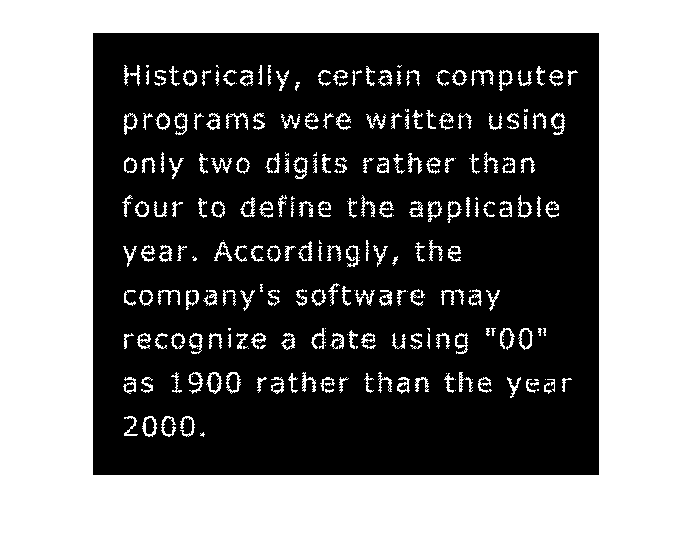

imoriginal=imread('broken-text.tif');
im = imoriginal;
imshow(im)

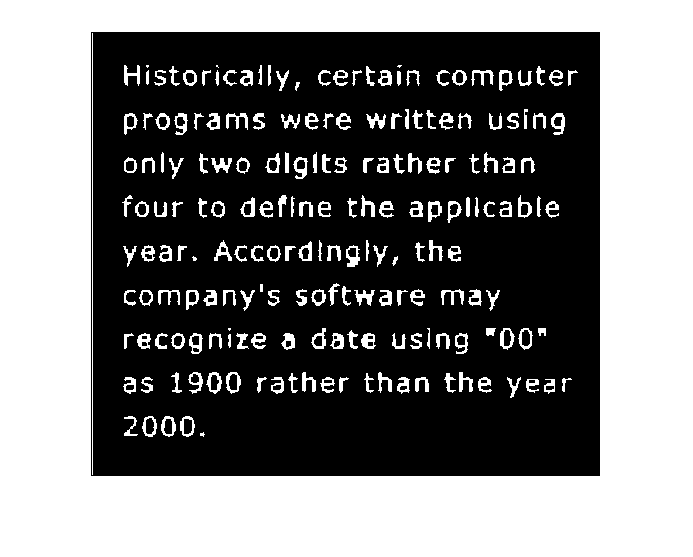


im=bwmorph(im,'close');
imshow(im)

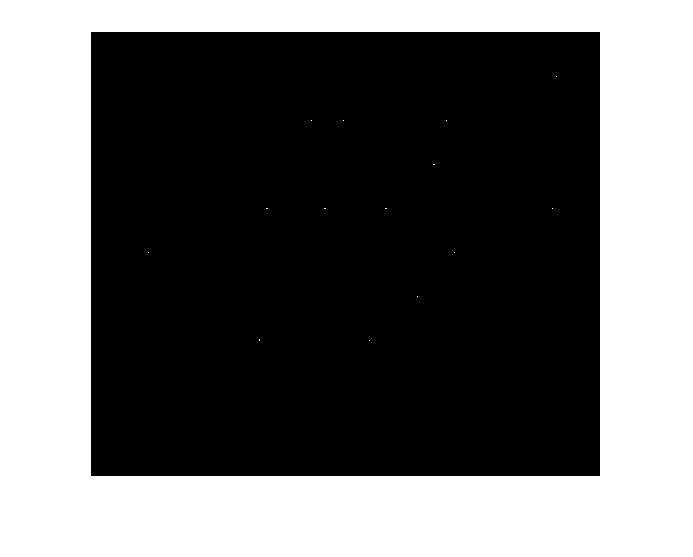



se =[
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 1 1 1 0 0 0 0 0 0 ;
0 0 0 0 1 0 0 0 0 0 1 0 0 0 0 0 ;
0 0 0 1 0 0 0 0 0 0 0 1 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 1 1 1 1 1 1 1 1 1 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 1 1 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 1 1 1 1 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ];

im =imerode(im,se);
imshow(im);



se=ones(18)

se =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1  

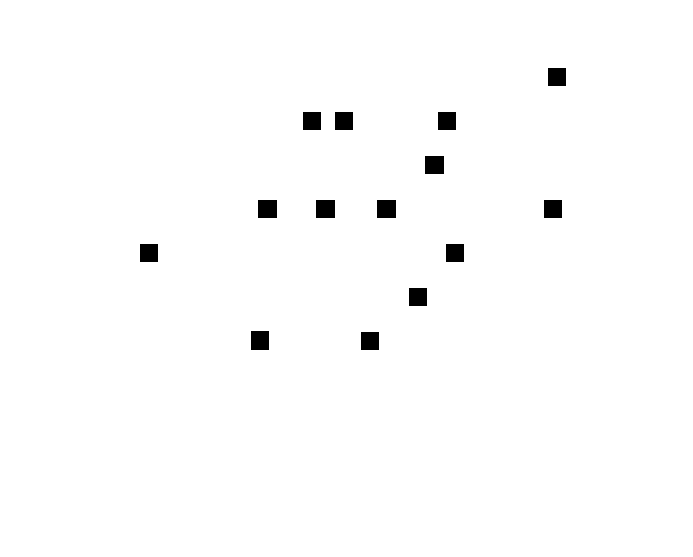

im2 = imdilate(im,se);
imshow(1-im2)


im_gaps = imoriginal.*(1-im2)

im_gaps =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0   

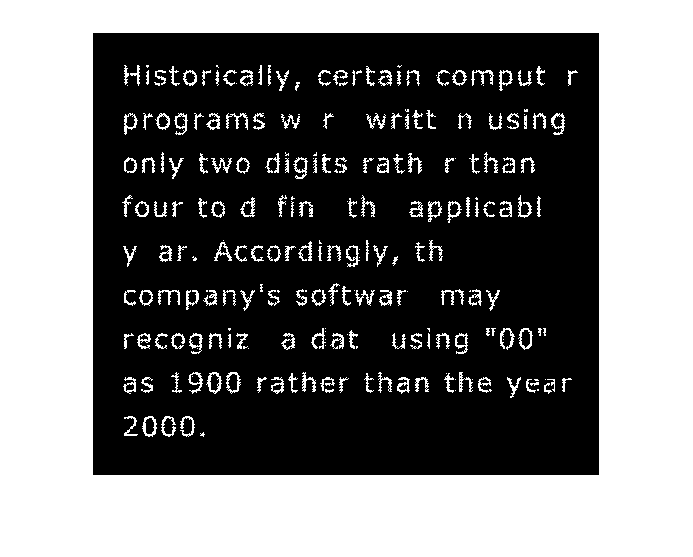

imshow(im_gaps)


se =[
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ;
0 0 0 0 0 1 1 1 1 1 0 0 0 0 0 0 ;
0 0 0 0 1 0 0 0 0 0 1 0 0 0 0 0 ;
0 0 0 1 0 0 0 0 0 0 0 1 0 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 1 0 0 0 0 0 0 0 0 0 1 0 0 0 ;
0 0 0 1 1 0 0 0 0 0 1 1 0 0 0 0 ;
0 0 0 0 0 1 1 0 0 1 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 0 ;
0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 ];

im = imdilate(im,se)

im = 444×509 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

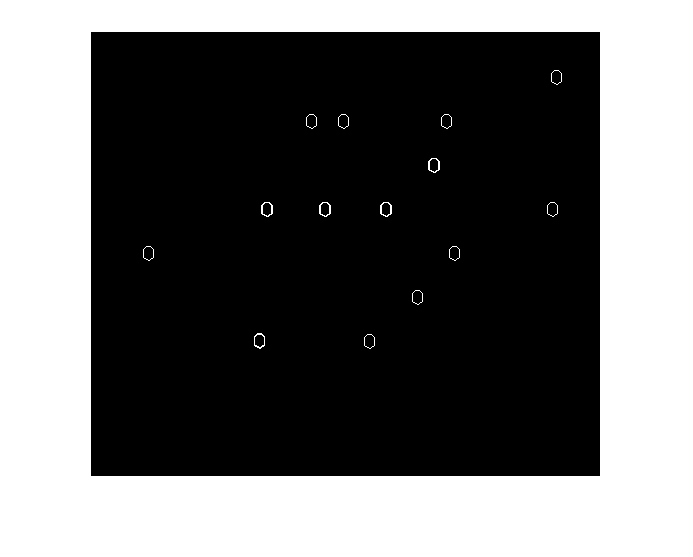

imshow(im)


im_result = im+im_gaps

im_result =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     0     0     0     0     0     0     0     0     0     0     0     0 

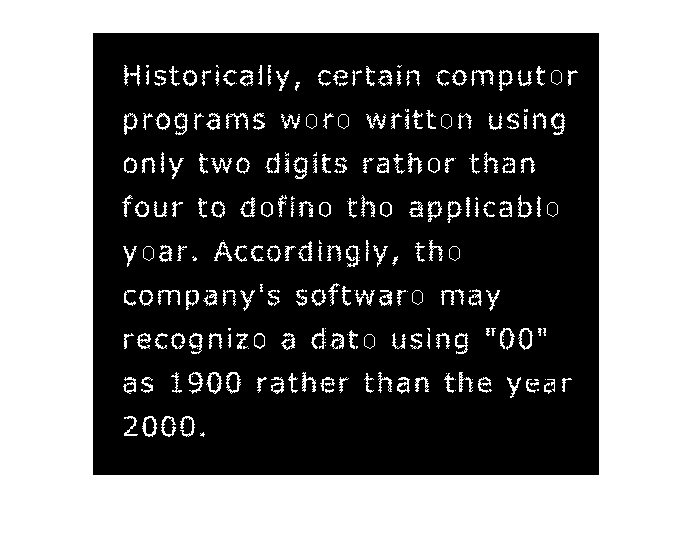

imshow(im_result)